clc; clear all; close all;

img_path = fullfile('fundus_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('data', 'metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);

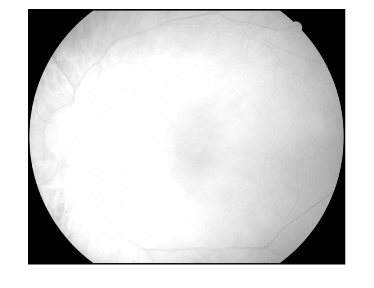

RGB = imread(string(fullfile(img_path, T{1,1})));%Aquí elijes la imagen
%RGB=imread('circulos.png');
R=RGB(:,:,1);

HSV=rgb2hsv(RGB);
V=HSV(:,:,3);
imshow(V,[]);

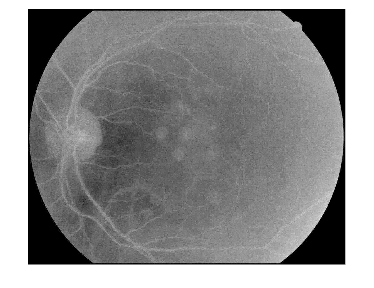


imshow(R,[]);

G=RGB(:,:,2);

B=RGB(:,:,3);

maxR=max(R(:));

maxG=max(G(:));

maxB=max(B(:)); 

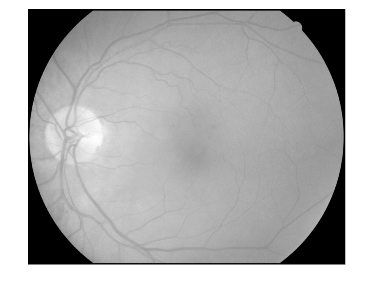

i2 = double(rgb2gray(RGB));%ahora he puesto R en vez de RGB, estoy probando
imshow(i2,[]);

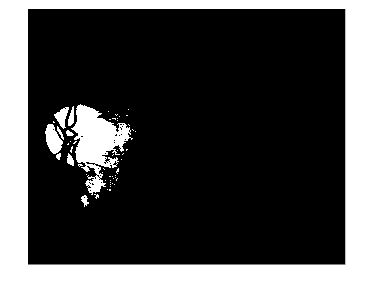

altos=i2>max(i2(:))*0.8;
imshow(altos,[]);

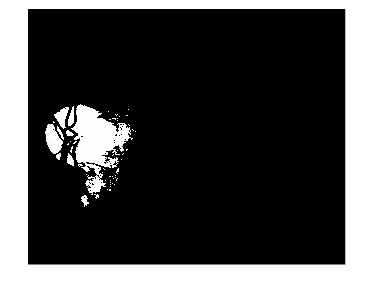

R=double(R);
i2b=R.*altos;
imshow(i2b,[]);

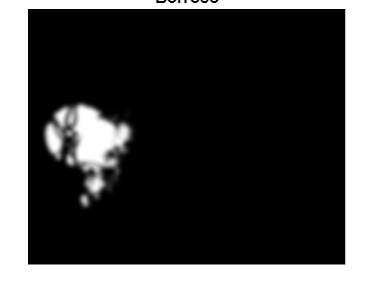


w2 = ones(50);
i2 = imfilter(i2b, w2);
i2 = imfilter(i2, w2);

imshow(i2,[]);
title('Borroso');

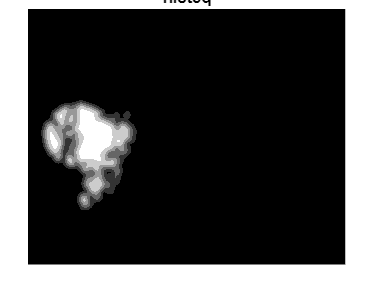

i2=i2.*255./max(i2(:));
i2=uint8(i2);
i2= histeq(i2);
imshow(i2,[]);
title('histeq');

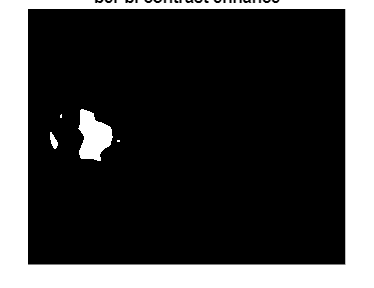

i2=double(i2);

i2=i2.^100;
i2=i2.*255./max(i2(:));
i2=i2.^100;
imshow(i2,[]);
title('ber bi contrast enhance');

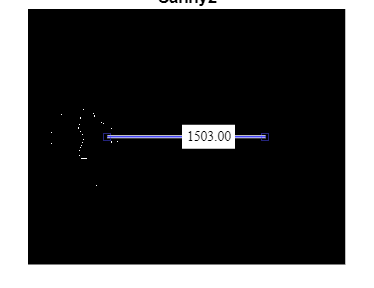

i2=i2.*255./max(i2(:));

%w2 = ones(150);
%i2 = imfilter(i2, w2);
%imshow(i2,[]);
%title('borroso ber bi contrast enhance');

iedge=edge(i2, 'Canny');

imshow(iedge);
%iedge3=edge(i2, 'Canny', 0.13);
%imshow(iedge3);
title('Canny2');
%iedge=iedge2-iedge3;
%imshow(iedge);
d=imdistline;

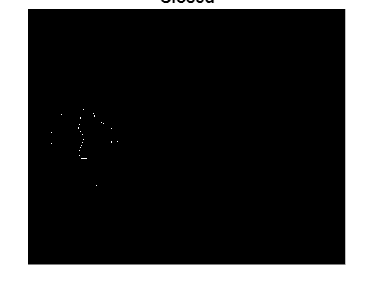

se = strel('disk',3);
closed=imclose(iedge, se);
figure;
imshow(closed);
title('Closed');

stats = regionprops('table', closed, 'Centroid', 'Eccentricity', 'EquivDiameter');

stats( stats.Eccentricity > .5 , : ) = []

%stats( stats.EquivDiameter > 1250 | stats.EquivDiameter < 1500 , : ) = []

figure;

imshow(i2);

hold on

viscircles(centers,radii)

hold off

figure;
imshow(RGB);
stats = regionprops("table",altos,"Centroid", ...
    "MajorAxisLength","MinorAxisLength")

stats = 266×3 table
        Centroid        MajorAxisLength    MinorAxisLength
    ________________    _______________    _______________

    240.31    1239.4        296.08             136.07     
     180.5    1300.5        2.3094             2.3094     
     183.8    1297.4        3.3066             2.1292     
     184.5      1304        2.3094             1.1547     
    216.74    1045.9        12.023             3.8307     
       225      1065        1.1547             1.1547     
     228.5      1048        2.3094             1.1547     
    231.57    1066.3        4.3128              2.228     
    244.86    1069.7        31.582             17.198     
    324.16    1023.5        202.29             115.05     
       257      1113        1.1547             1.1547     
       261      1084        1.1547             1.1547     
       291    1398.4        70.351             46.0

centers = stats.Centroid;
diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
radii = diameters/2;
hold on
viscircles(centers,radii)

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


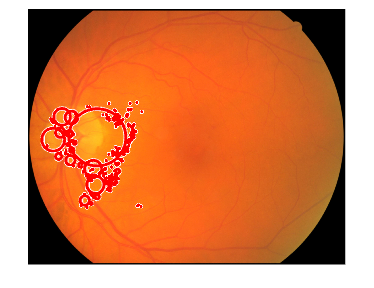

hold off